% define mean and sd
mu1 = [0.4; 0.6];
sd1 = [0.9; 0.7];

mu2 = [2.5; 3.0];
sd2 = [0.9; 0.7];

% sizes
train_size = 1800;
c1_train_size = 1000;
c2_train_size = 800;

test_size = 900;
c1_test_size = 500;
c2_test_size = 400;

% Training set
% Class 1 - 1000
X_train_c1 = randn(2, c1_train_size) .* sd1 + mu1;
Y_train_c1 = ones(1, c1_train_size);

% Class 2 - 800
X_train_c2 = randn(2, c2_train_size) .* sd2 + mu2;
Y_train_c2 = -1*ones(1, c2_train_size);

X_train = [X_train_c1, X_train_c2];
Y_train = [Y_train_c1, Y_train_c2];

% Testing set
% Class 1 - 500
X_test_c1 = randn(2, c1_test_size) .* sd1 + mu1;
Y_test_c1 = ones(1, c1_test_size);

% Class 2 - 400
X_test_c2 = randn(2, c2_test_size) .* sd2 + mu2;
Y_test_c2 = -1*ones(1, c2_test_size);

X_test = [X_test_c1, X_test_c2];
Y_test = [Y_test_c1, Y_test_c2];

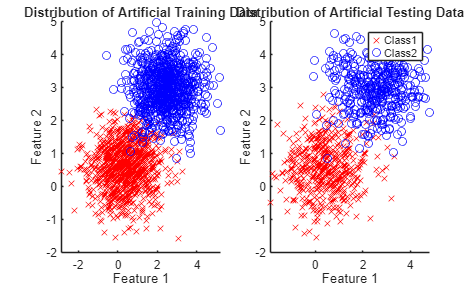

% Plot training data
figure;
subplot(1,2,1);
scatter(X_train_c1(1,:), X_train_c1(2,:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(X_train_c2(1,:), X_train_c2(2,:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
hold off;

title('Distribution of Artificial Training Data');
xlabel('Feature 1');
ylabel('Feature 2');

% Plot test data
subplot(1,2,2);
scatter(X_test_c1(1,:), X_test_c1(2,:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(X_test_c2(1,:), X_test_c2(2,:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
hold off;

title('Distribution of Artificial Testing Data');
legend('Class1', 'Class2');
xlabel('Feature 1');
ylabel('Feature 2');

# LDA - implementation

% 2x1 mean per feature
mean_class_one = mean(X_train_c1, 2); 
mean_class_two = mean(X_train_c2, 2);
% 2x2 covariance matrix for the 2 features of each class
cov_class_one = cov(X_train_c1(1,:), X_train_c1(2,:));
cov_class_two = cov(X_train_c2(1,:), X_train_c2(2,:));
% common covariance matrix - weighted average of individual class
% covariance matrices
combined_cov = ((c1_train_size - 1) * cov_class_one + (c2_train_size - 1) * cov_class_two) / (train_size - 2); 

% Compute projection vector
w = (combined_cov^-1) * (mean_class_one - mean_class_two);

% Compute bias
p1 = c1_train_size / (train_size);
p2 = c2_train_size / (train_size);
b = -0.5 * (mean_class_one') * (combined_cov^-1) * mean_class_one + 0.5 * (mean_class_two') * (combined_cov^-1) * mean_class_two  + log(p1/p2); 

% Result for test set
result = sign(w' * X_test + b);
correct = (result == Y_test);
accuracy_test = sum(correct) / (test_size);
fprintf('Test Set Accuracy: %.2f%%\n', accuracy_test * 100);

Test Set Accuracy: 97.44%


% Result for train set
result_train = sign(w' * X_train + b);
accuracy_train = sum(result_train == Y_train) / (train_size);
fprintf('Train Set Accuracy: %.2f%%\n', accuracy_train* 100);

Train Set Accuracy: 98.56%


% Compute decision line. We have 2 features x1 and x2 -> w1*x1 + w2*x2 + b.
% We need 2 points to define a line so just take max and min values of x1 and 
% find what are the corresponding x2 values via
% x2 = (-w1*x1 - b) / w2.
x1_min = min(X_train(1,:));
x1_max = max(X_train(1,:));

x2_one = (-w(1) * x1_min - b) / w(2);
x2_two = (-w(1) * x1_max - b) / w(2);

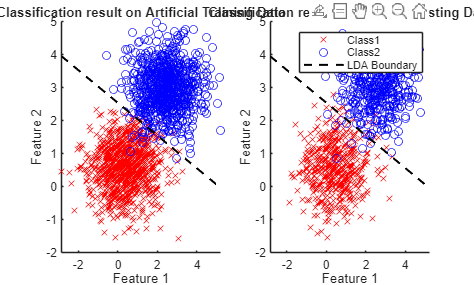

% Plot resutls
% Plot training data
figure;
subplot(1,2,1);
scatter(X_train_c1(1,:), X_train_c1(2,:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(X_train_c2(1,:), X_train_c2(2,:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
plot([x1_min, x1_max], [x2_one, x2_two], '--k', 'LineWidth', 1.5);
hold off;

title('Classification result on Artificial Training Data');
xlabel('Feature 1');
ylabel('Feature 2');

% Plot test data
subplot(1,2,2);
scatter(X_test_c1(1,:), X_test_c1(2,:), 'red', 'x', 'MarkerFaceAlpha', 0.5);
hold on;
scatter(X_test_c2(1,:), X_test_c2(2,:), 'blue', 'o', 'MarkerFaceAlpha', 0.5);
plot([x1_min, x1_max], [x2_one, x2_two], '--k', 'LineWidth', 1.5);
hold off;

title('Classification result on Artificial Testing Data');
legend('Class1', 'Class2', 'LDA Boundary');
xlabel('Feature 1');
ylabel('Feature 2');

# Test custom LDA

[acc_train, acc_test, w, b, line] = custom_LDA(X_train, Y_train, X_test, Y_test);

Test Set Accuracy: 97.44%
Train Set Accuracy: 98.56%
